### **Substrates leading to product-only metabolites**

**Description**: Find and display all linear, non-branching metabolic paths that:

- Move from one metabolite to another (substrate → product),

- Are represented as a graph of metabolites (not reactions),

- Have no bifurcations (i.e., each node has out-degree = 1),

- And ultimately end at a product-only metabolite.

#### **Part 1:** Build the Metabolite Graph

**Description**: The code loops through each reaction in your metabolic model. For each reaction:

- Finds substrates (where `S(met, rxn) < 0`) and products (`S(met, rxn) > 0`).

- Then creates edges from each substrate to each product. So if `A → B + C`, you'll create: `A → B and A → C`

**Result**: Two lists `sourceMets` and `targetMets` with parallel entries, forming directed edges from substrate to product.

% Build substrate → product edges from model
sourceMets = {};
targetMets = {};

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%for validation only
model.S=[ 1  -1  0  0  0; 
          0  1  -1  0  0; 
         -1  0   0  0  0; 
          0  0  -1  0  1;
          0  0 -1   -1 -1;
          0  0  1   1  0];
model.mets{1}='met_1';
model.mets{2}='met_2';
model.mets{3}='met_3';
model.mets{4}='met_4';
model.mets{5}='met_5';
model.mets{6}='met_6';
only_product_mets={'met_6'};
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for rxnIdx = 1:size(model.S,2)
    substratesIdx = find(model.S(:, rxnIdx) < 0);
    productsIdx   = find(model.S(:, rxnIdx) > 0);

    for s = 1:length(substratesIdx)
        for p = 1:length(productsIdx)
            sourceMets{end+1} = model.mets{substratesIdx(s)}; 
            targetMets{end+1} = model.mets{productsIdx(p)}; 
        end
    end
end

#### Part 2: Create and Simplify the Graph

Create a directed graph (`digraph`) where:

- Nodes = metabolite IDs

- Edges = substrate → product

G = digraph(sourceMets, targetMets);

Removing:

- Self-loops (e.g., `A → A`)

- Duplicate edges

G = simplify(G, 'omitselfloops');



#### Part 3: Define Product-Only Endpoints

**Description**:

- It filters the `only_product_mets` list (your input) to include only those metabolites that are actually in the graph.

- These are the target endpoints of the paths you're looking for.

% Convert product-only metabolites to graph node names
product_only_nodes = intersect(G.Nodes.Name, only_product_mets);

#### Part 4: Identify Starting Points for Paths

**Description**:

- Identify nodes with exactly one outward connection — i.e., they can be the beginning of a linear path.

- We don't care about in-degree (a node can be made from many reactions), but we do care that it only contributes to one next step.

% Start condition: nodes with out-degree = 1 (can have any in-degree)
starts = find(outdegree(G) == 1);

#### Part 5: Trace Paths

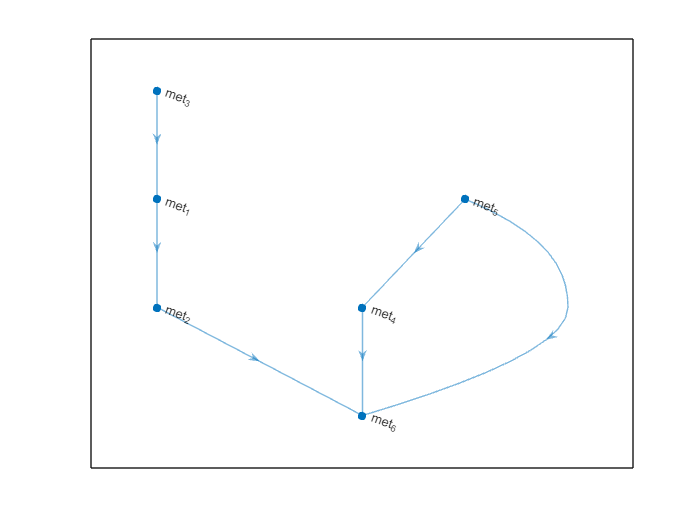

% Initialize list of linear paths
linear_paths = {};
% Loop through each start node
for i = 1:length(starts)
    path = G.Nodes.Name(starts(i));%temporal variable to save the path from start nodes
    current = starts(i);%flag to avoid visiting the same node multiple times

    visited = false(height(G.Nodes), 1); % to avoid cycles

    % Trace forward until bifurcation or endpoint
    % While-loop: keeps walking through the path.
    % Stops if: no next node (dead end).
    while true
        visited(current) = true;%flag set to one as this node is currently visited
        successors_list = successors(G, current);%look for the child node from the current one

        % Stop if path ends
        if isempty(successors_list)
            break;
        end

        %find the name of the child node
        next_name = G.Nodes.Name{successors_list(1)};
        %find the index of the child node
        next = find(strcmp(G.Nodes.Name, next_name));

        % Stop if bifurcation or already visited (avoid cycles)
        if outdegree(G, next) > 1 || visited(next)
            break;
        end

        % If there is any biffurcation add next node
        path{end+1} = next_name;
        %place the current node with the next visiting one
        current = next;
    end

    % The above while-loop path is recorded only if path ends at a product-only metabolite
    if ismember(path{end}, product_only_nodes)
        linear_paths{end+1} = path;
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%for validation only
figure;
plot(G)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Display paths
if isempty(linear_paths)
    fprintf('There is any single substrate to a metabolite-product only');
else
    for i = 1:length(linear_paths)
        fprintf('Linear (non-branching) pathways that lead to product-only metabolites:\n\n');
        fprintf('Path %d:\n', i);
        disp(strjoin(linear_paths{i}, ' → '));
    end
end

Linear (non-branching) pathways that lead to product-only metabolites:



Path 1:


met_3 → met_1 → met_2 → met_6


Linear (non-branching) pathways that lead to product-only metabolites:



Path 2:


met_1 → met_2 → met_6


Linear (non-branching) pathways that lead to product-only metabolites:



Path 3:


met_2 → met_6


Linear (non-branching) pathways that lead to product-only metabolites:



Path 4:


met_4 → met_6
